clear;clc;
mFile='../mask2m_16_16.mat';load(mFile);% mask2m 304x304x361

% Get the dimensions of the data
[h, w, c] = size(mask2m);

% Reshape the data into a 2D matrix
x = reshape(mask2m, h * w, c);


% Calculate the FFT of each pixel 
fftx=fft(x,c,2);
fftx = fftx(:,1:181);
% Calculate the magnitude (abs) of fftx
ffty = (real(fftx.* conj(fftx))).^.5;

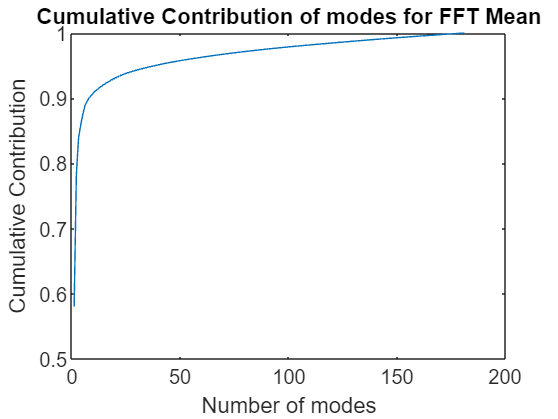


% Calculate the mean Magnitude in each frequency
fftM = mean(ffty, 1);

% Sort fftM in descending order, Morder is the index of original fftM
[fftM, Morder] = sort(fftM, 'descend');


% Calculate the cumulative contribution of modes of fftM

plot(cumsum(fftM)./sum(fftM));
xlabel('Number of modes');
ylabel('Cumulative Contribution');
title('Cumulative Contribution of modes for FFT Mean');

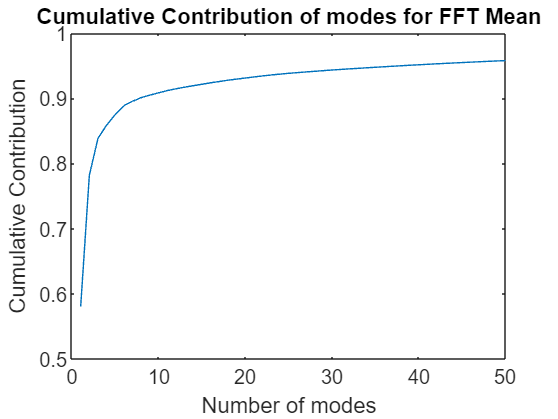



plot(cumsum(fftM(1:50))./sum(fftM))
xlabel('Number of modes');
ylabel('Cumulative Contribution');
title('Cumulative Contribution of modes for FFT Mean');

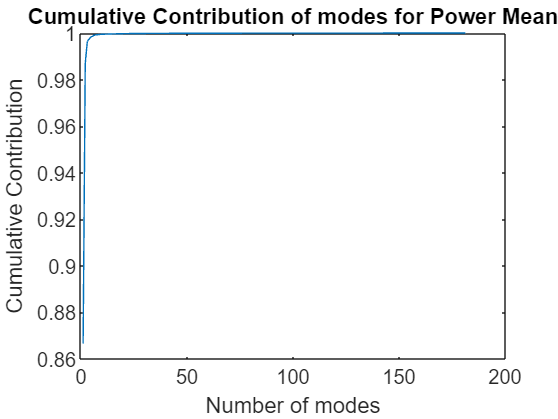

% Calculate the mean Power in each frequency
fftP = mean(ffty.^2, 1);

% Sort fftM in descending order, Morder is the index of original fftM
[fftP, Porder] = sort(fftP, 'descend');


% Calculate the cumulative contribution of Frequencies

plot(cumsum(fftP)./sum(fftP));
xlabel('Number of modes');
ylabel('Cumulative Contribution');
title('Cumulative Contribution of modes for Power Mean');

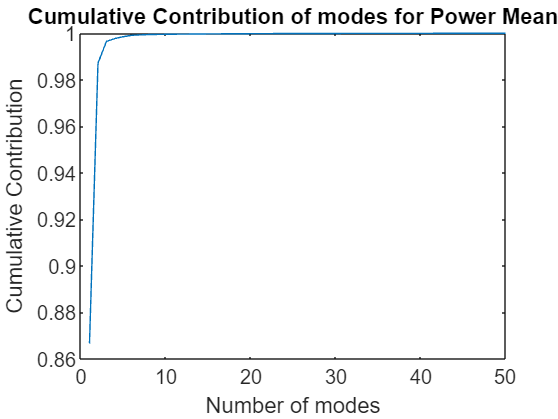



plot(cumsum(fftP(1:50))./sum(fftP))
xlabel('Number of modes');
ylabel('Cumulative Contribution');
title('Cumulative Contribution of modes for Power Mean');

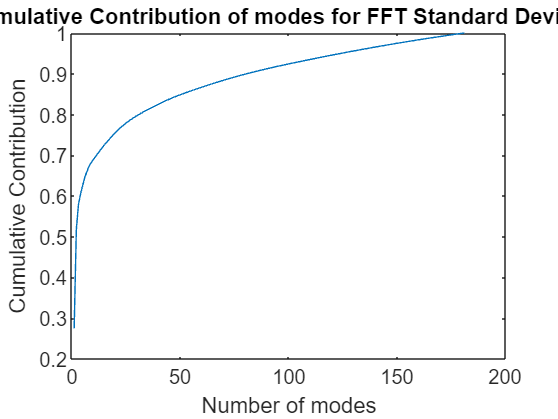


% Calculate the standard deviation of fft
fftS = std(ffty, 0, 1);


% Sort fftS in descending order, Sorder is the index of original fftS
[fftS, Sorder] = sort(fftS, 'descend');

% Calculate the cumulative contribution of modes of fftS
%
plot(cumsum(fftS)./sum(fftS));
xlabel('Number of modes');
ylabel('Cumulative Contribution');
title('Cumulative Contribution of modes for FFT Standard Deviation');

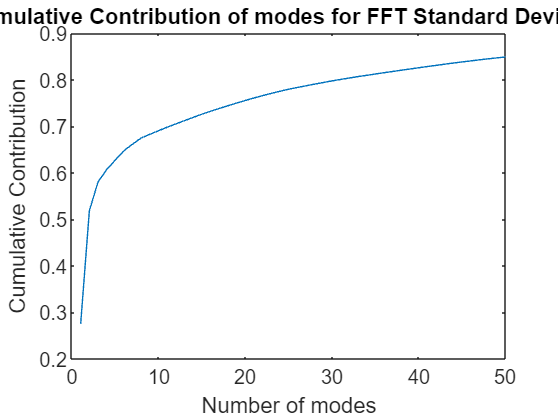


plot(cumsum(fftS(1:50))./sum(fftS))
xlabel('Number of modes');
ylabel('Cumulative Contribution');
title('Cumulative Contribution of modes for FFT Standard Deviation');

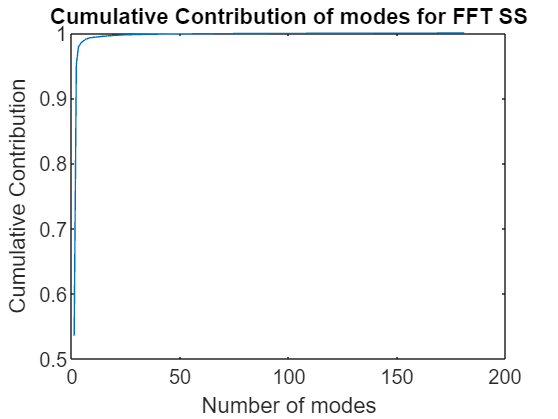

% SS
% Calculate the standard deviation of fft
fftSS = var(ffty, 0, 1)*(size(ffty,1)-1);

[fftSS, SSorder] = sort(fftSS, 'descend');

% Calculate the cumulative contribution 
plot(cumsum(fftSS)./sum(fftSS));
xlabel('Number of modes');
ylabel('Cumulative Contribution');
title('Cumulative Contribution of modes for FFT SS');

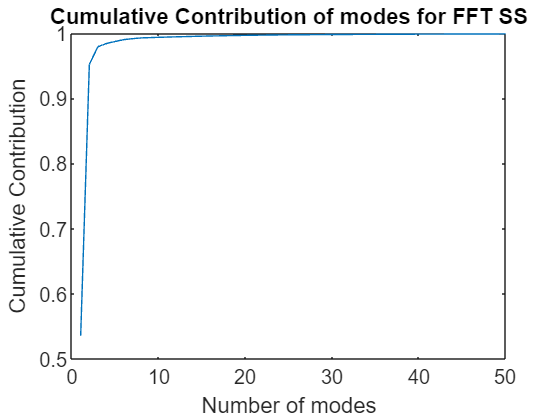


plot(cumsum(fftSS(1:50))./sum(fftSS))
xlabel('Number of modes');
ylabel('Cumulative Contribution');
title('Cumulative Contribution of modes for FFT SS');

KsM =  find(cumsum(fftM)./sum(fftM)<=.95)

KsM =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38


KsS =  find(cumsum(fftS)./sum(fftS)<=.95)

KsS =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


KsP =  find(cumsum(fftP)./sum(fftP)<=.99)

KsP =      1     2


KsSS =  find(cumsum(fftSS)./sum(fftSS)<=.99)

KsSS =      1     2     3     4     5     6


Morder(KsM)

ans =      1     2     3     4     5     6     7     8    10     9    11    12    14    13    17    18    20    15    19    21    16    23    24    26    27    22    30    42    32    31    29    25    45    38    28    44    35    39


Sorder(KsS)

ans =      1     2     3     4     6     5     8     7    10    18    11    17    20     9    14    12    15    21    19    24    23    13    26    16    27    31    30    32    42    22    29    45    38    44    25    35    28    39    48    43    36    41    56    50    51    53    47    33    55    34


Porder(KsP)

ans =      1     2


SSorder(KsSS)

ans =      1     2     3     4     6     5


The 38 index found by KsM seems to be more reasonable.

## Reconstruction Error

iPixel = 10;
iY = x(iPixel,:);
iYfft = fft(iY);
[~, iMorder] = sort(iYfft(1:181), 'descend');
if iMorder(1)~=1
    iMorder = [1, setdiff(iMorder, 1)];
end

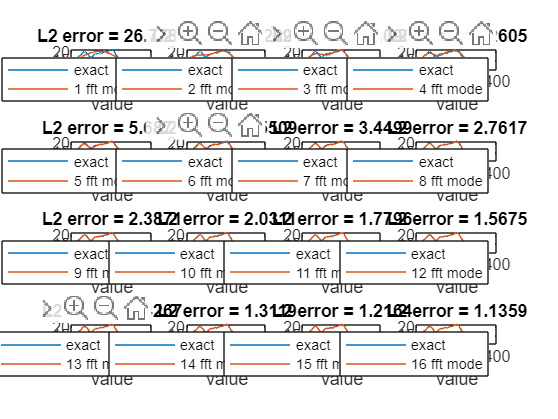

K = 16;
figure;
for j = 1:K
    % Use top j frequency components
    jIdx = [iMorder(1) iMorder((1:j)+1) 361+2-iMorder((j:-1:1)+1)];
    
    % Reconstruct the signal
    jYfft = zeros(size(iYfft));
    jYfft(jIdx) = iYfft(jIdx);
    iYr = ifft(jYfft);
    
    % Create a subplot for each mode
    subplot(K/4, 4, j);
    
    % Plot the original data and the reconstructed data
    plot(iY); hold on; plot(iYr);
    
    % Set title with L2 error information
    title(['L2 error = ' num2str(norm(iY - iYr))], 'FontWeight', 'bold');
    
    % Set labels and legend
    xlabel('value');
    legend('exact', [num2str(j), ' fft mode']);
end

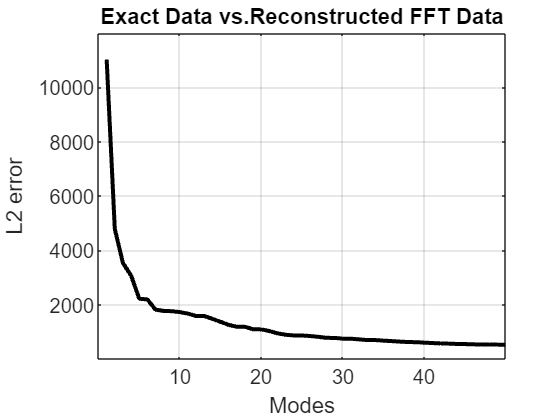

K=50;
% fftx is complete fft
% The Mean Magnitude order is used: Morder
L2error = zeros(K,1);
Linferror = zeros(K,1);
for j = 1:K
    % Use top j frequency components
    jIdx = [Morder(1) Morder((1:j)+1) 361+2-Morder((j:-1:1)+1)];
    % Reconstruct
    jYfft = zeros(size(fftx));
    jYfft(:, jIdx) = fftx(:, jIdx);
    fftxr = ifft(jYfft, c, 2);
    % Calculate Error
        % Calculate L2 and L infinity errors
    L2error(j) = norm(x - fftxr, 2);
    Linferror(j) = norm(x - fftxr, inf);
end

figure;
plot(L2error,Color=[0,0,0],LineWidth=2)
xlabel('Modes');
ylabel('L2 error');
grid on;
title('Exact Data vs.Reconstructed FFT Data','FontWeight','bold');

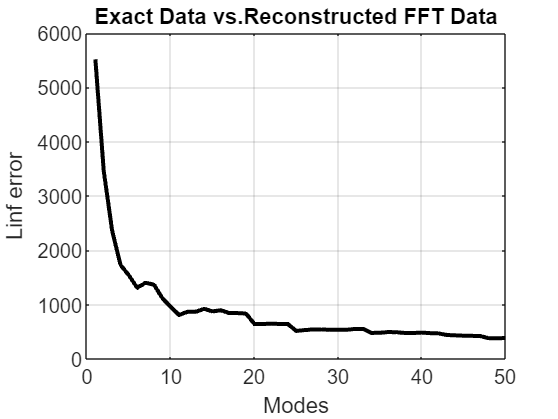



figure;
plot(Linferror,Color=[0,0,0],LineWidth=2)
xlabel('Modes');
ylabel('Linf error');
grid on;
title('Exact Data vs.Reconstructed FFT Data','FontWeight','bold');